# 测试题 (学生用)

建议用时30分钟.

请在一对注释标记之间, 填入本题需要的代码.

请在文本标记的空白处, 填入需要描述的内容.

技巧: 每小题被蓝色横线分隔, 按Ctrl+Enter能够只运行一个蓝色代码小节.

第1题

修改Monte-Carlo模拟次数为1e2, 1e3, 1e4次, 比较结果.

clear
close all
data = xlsread("QTTN_2015_2019.xlsx");
rtn = diff(log(data));
n = length(rtn);
k = 250;
kn = 10000  % 在方框中填写数字

kn = 10000

rtn_train = rtn(1:n-k);

请在以下空白处写清不同模拟次数时, VaR的超限次数:

第2题

对本题的数据进行garch模型定阶.

第3题

请在此处填入定阶结果.

p =2

p = 2

q =3

q = 3

model = garch(p,q);  % p: autoregression, q: residuals^2
model = estimate(model, rtn_train);

 
    GARCH(2,3) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic     PValue  
                __________    _____________    __________    _________

    Constant    8.2473e-06      5.373e-06        1.5349         0.1248
    GARCH{1}       0.43816         1.1272        0.3887        0.69749
    GARCH{2}       0.36357        0.97907       0.37135        0.71038
    ARCH{1}       0.077083       0.027463        2.8068      0.0050032
    ARCH{2}       0.066077       0.093873        0.7039         0.4815
    ARCH{3}       0.034692       0.054063       0.64169        0.52107



第4题

请修改本节代码, 假设收益率服从t分布, 置信水平为99%.

[~,rtn_simu] = simulate(model, k, 'NumPaths', kn);
rtn_simu = rtn_simu';
VaR = mean(rtn_simu) - norminv(.90)*std(rtn_simu);

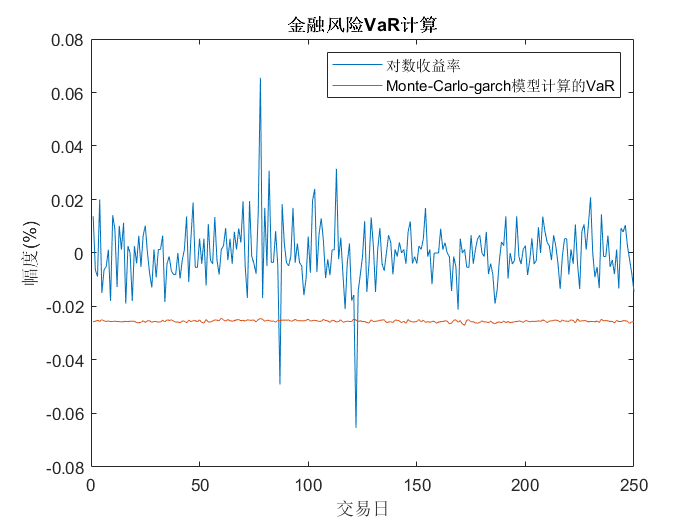

plot(rtn(n-k+1:end)); hold on;
plot(VaR);
hold off
legend({'对数收益率', 'Monte-Carlo-garch模型计算的VaR'});
ylabel('幅度(%)');
xlabel('交易日');
title('金融风险VaR计算');

exceed = sum(rtn(n-k+1:end) < VaR');
fprintf('超限次数: %d\n', exceed);

超限次数: 2
